% This function initializes the fluid simulation with animation
% The user must correctly compute the following variables:
%   A, B, C, D for the state space model.
% The output should be a vector of N pressures in N/m/m.
% The user must also specify a vector of the N tank Heights.
% 
% The following specifies arbitrary matrices of the compatible dimensions
% and then opens the simulation with the animation.

clear all
close all
rho  =   1000;  % fluid density, kg/m/m/m
g    =   9.8;   % gravity, m/s/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## The following section of code computes the fluid resistances and

## capacitances.

L1  = 0.5;      % length of pipe 1
d1  = 0.04;     % inside diameter of pipe 1
R1  = pipe_resistance(L1,d1)

R1 = 7.9577e+03


L2  = 1;        % length of pipe 2
d2  = 0.04;     % inside diameter of pipe 2
R2  = pipe_resistance(L2,d2)

R2 = 1.5915e+04


L3  = 1;        % length of pipe 3
d3  = 0.03;     % inside diameter of pipe 3
R3  = pipe_resistance(L3,d3)

R3 = 5.0301e+04


L0  = 1;        % length of output pipe 
d0  = 0.02;     % inside diameter of output pipe 
R0  = pipe_resistance(L0,d0)

R0 = 2.5465e+05


A1  = 2;        % crossectional area of Tank 1
C1  = tank_capacitance(A1,rho,g)

C1 = 2.0408e-04


A2  = 0.5;      % crossectional area of Tank 2
C2  = tank_capacitance(A2,rho,g)

C2 = 5.1020e-05


A3  = 0.1;      % crossectional area of Tank 3
C3  = tank_capacitance(A3,rho,g)

C3 = 1.0204e-05

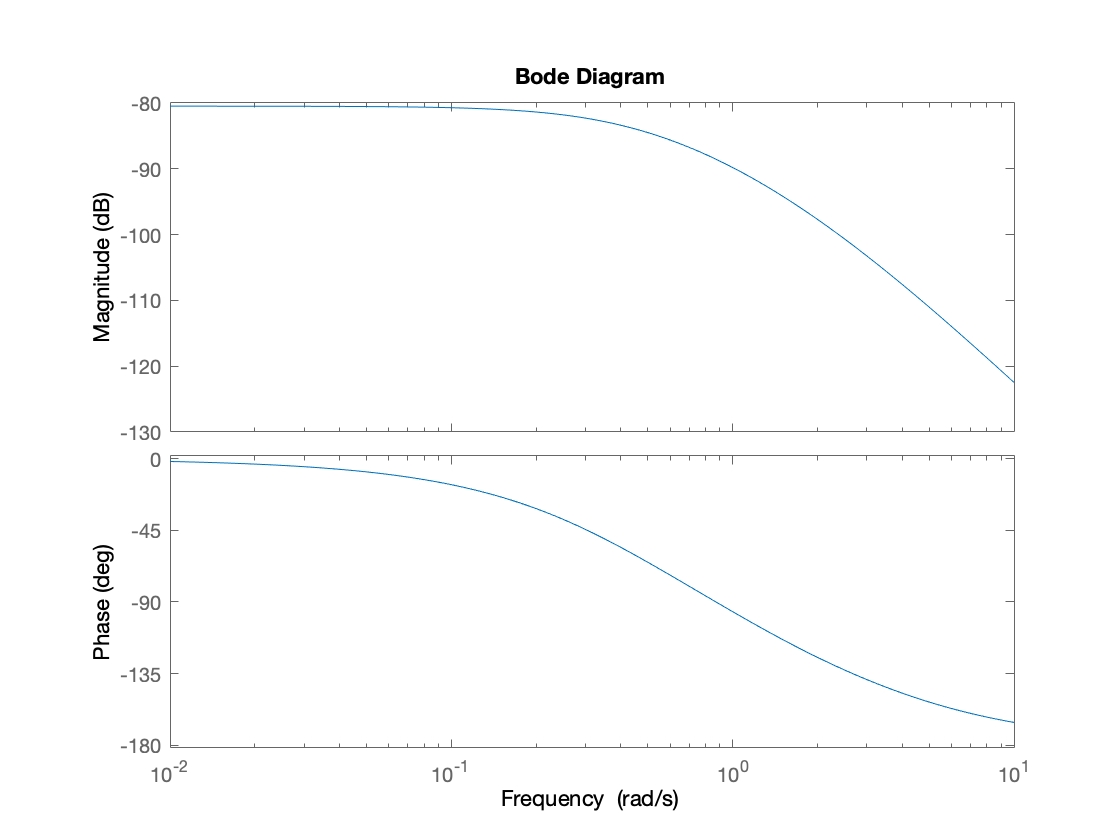


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% The following code sets up the state space model in matrix form.
% Currently, the A, B, C, and D matrices are incorrect, but have the right
% dimensions.  Derive the model, then update the following code with the
% correct model parameters.  If the state space model is not correct, the
% the simulation may give an error message about a tank being either empty
% or full.
n=3;
m=4;
% The 
A = [(-1/(C1*R1) -1/(C1*R2))   1/(C1*R2)   0;...
    1/(C2*R2)    -(1/(C2*R2) + 1/(C2*R3))  1/(C2*R3);...
    0   1/(C3*R3)   -(1/(C3*R3) + 1/(C3*R0))];
B = [1/(C1*R1); 0; 0];
C = [1/(rho*g) 0 0;...
    0 1/(rho*g) 0;...
    0 0 1/(rho*g);...
    0 0 1/R0];
D = zeros(m,1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% use code similar to the following for the Bode (Frequnecy response)
% analysis.
w=logspace(-2,1,100);
bode(A,B,C(2,:),D(2,:),1,w) % height tank 2


Xo= 0*rho*g*ones(n,1)/2;        % Tanks start empty

% Do not change the following until requested to do so..
global Height
Height = [1.0957,0.9549,0.7840];       % Tank Heights, m
omega_0=w(91);                       % Pump rotation rate, rad/s

fluid_animated      % opens the simulink file

Undefined function or variable 'fluid_animated'.